# Optical tweezers summer school 2024

# December 11-15, Santiago, Chile

## Suggested solutions to exercises

Are Mjaavatten

## Preparations

After the course I have added some files and made corrections to some of the others.  So please download all files from [https://github.com/are-mj/OpticalTweezers](https://github.com/are-mj/OpticalTweezers) once more.  

The file 'experiment_files.zip' now contains all the experiment files and corresponding COM files used in the exercises.

I have stored those files on my computer in the subfolder 'summerschool24' under my data folder

'C:\Users\mjaav_hi6z2cj\OneDrive\Data\Chile'

Please create a corresponding data folder and subfolder on your computer and store the files from experiment_files.zip there.

To avoid having to type this long path every time I have created the file datafolder.m:

function folder = datafolder
  folder = 'C:\Users\are\OneDrive\Data\Chile';
end

You should create your own version of this file so that it returns the path to your data folder.

Please see Exercises.ppt for the exercises text.  

## Exercise 1

### 1A

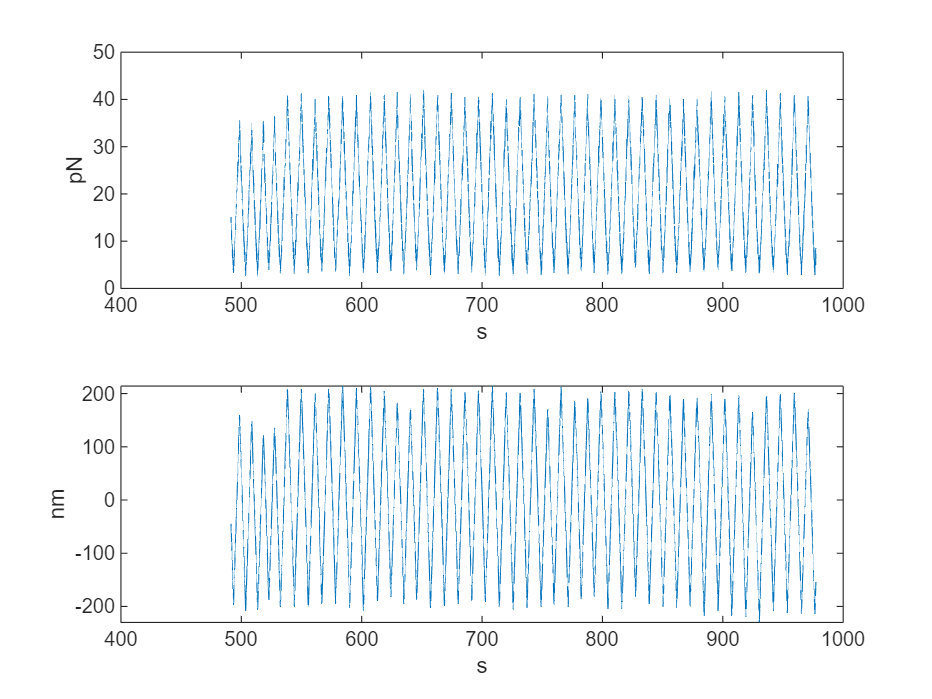

[t,f,x,T] = read_experiment_file('summerschool24/sB.txt');
figure; tiledlayout(2,1);
ax1 = nexttile; plot(t,f); xlabel s; ylabel pN
ax2 = nexttile; plot(t,x); xlabel s; ylabel nm
linkaxes([ax1,ax2],'x')  % Couple zoom and pan in both axes

By zooming in and panning we see that tne first rips at around t=497s, f=26pN and t=507.5s, f=29pN.  Zips are less obvious, but there seems to be ones at t=502.5. f = 7.5pN and t=513s, f = 6pN.

### Exercise 1**B**

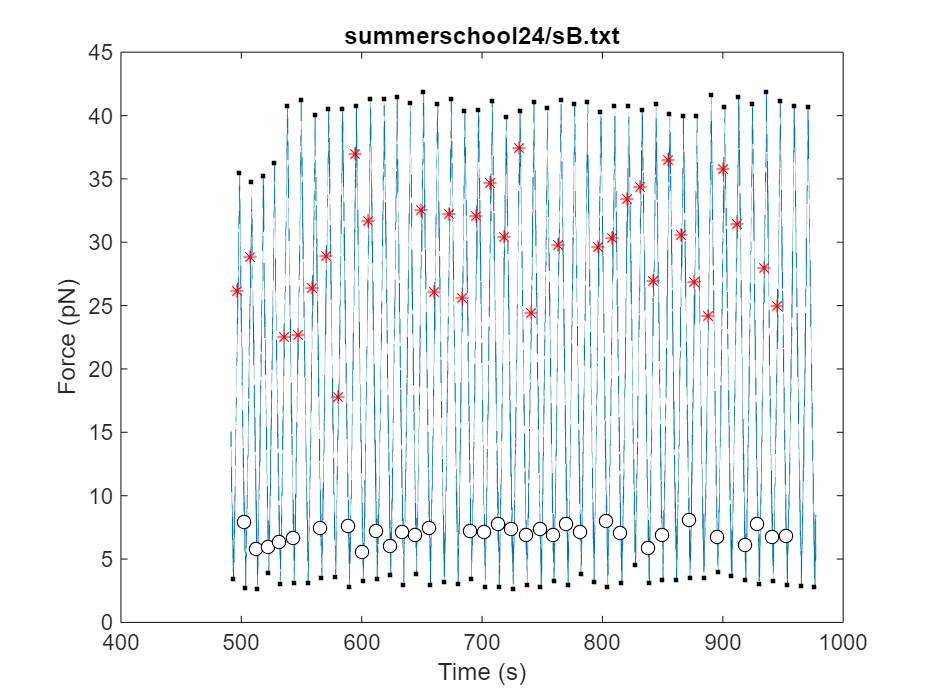

[Trip,Tzip] = analyse_experiment('summerschool24/sB.txt',1);

The exercise text says to use the datacursor tool to report the result of the automatic analysis.  It is simpler to use the results tables:

[Trip.Time(1:2),Trip.Force(1:2)]

ans =   497.0910   26.2081
  507.7360   28.8918


[Tzip.Time(1:2),Tzip.Force(1:2)]

ans =   502.4960    7.9494
  512.9910    5.8014


The automatic analysis agrees quite well with the visual estimates.

### Exercise 1C: Δx and force shift

For this exercise we need to return variables t and f:

[Trip,Tzip,pull,relax,t,f,x,T] = analyse_experiment('summerschool24/sB.txt',1);

The code below makes the plot appear as it did after my zom, pan and using the datacursor tool:

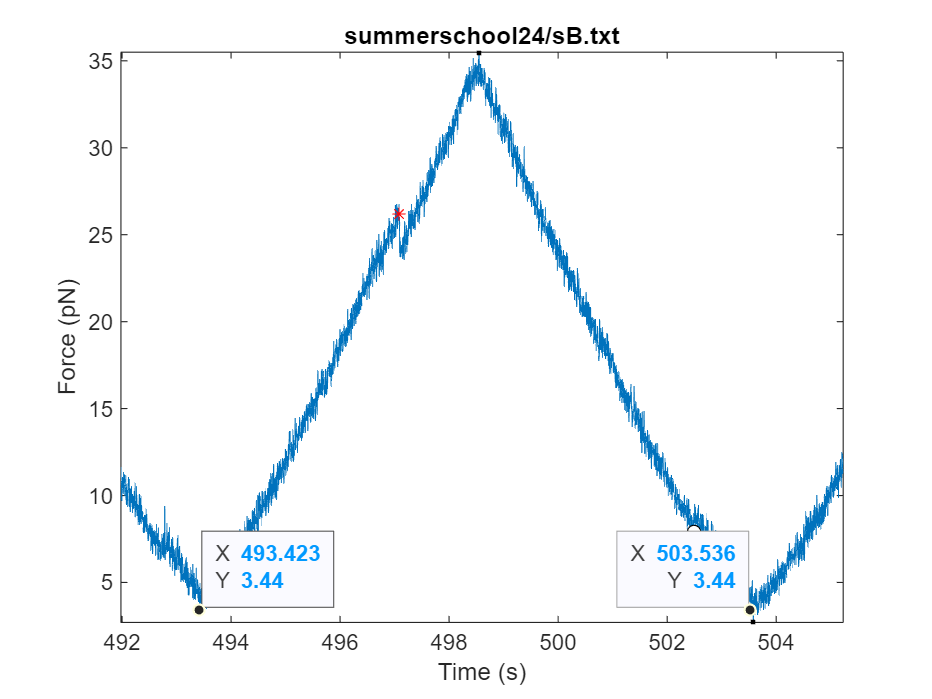

xlim([491.98 505.23])
ylim([2.7 35.5])
 
ax = gca;
chart = ax.Children(5);
datatip(chart,503.5,3.44);
chart = ax.Children(3);
datatip(chart,493.4,3.44);

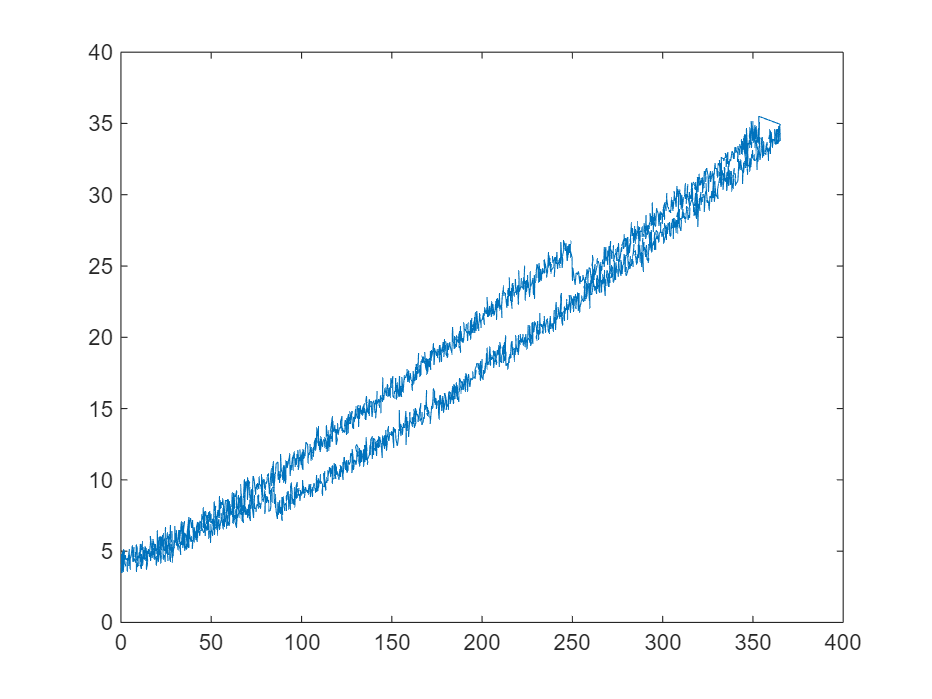

t1 = 493.4;t2 = 503.5;
ok = t > t1 & t < t2;
figure; plot(x(ok),f(ok))

**NOTE: Zooming and panning may be easier if you create the plot from the Matlab command window**

The main cause of the measurement noise is random motion of the trapped bead. The mechanism is the same as in [brownian motion,](https://en.wikipedia.org/wiki/Brownian_motion) except that the bead movements are restricted by the optical trap. This noise makes it difficult to find representative values for x and f, but reasonable estimates are:

Ar the rip: f = 26.2pN : x = 249nm. After rip:  f = 24pN. 

At recovered pulling force: x = 268nm, so Δx = 19nm and the force shift = -2.2pN.

At the zip: f 7.9pN  x = 87nm.  

After zip; f = 8.5.  At recovered force: x = 75nm, so Δx =12nm, Force shift = -0.6pN.

### Exercise 1D: Compare with automatic results

[19,2.2;Trip.Deltax(1),Trip.Forceshift(1)]

ans =    19.0000    2.2000
   25.7202    2.1930


[-12,-0.6;Tzip.Deltax(1),Tzip.Forceshift(1)]

ans =   -12.0000   -0.6000
  -15.3648   -0.8290


Not bad!

## Exercise 2: The RipAnalysis app

This exercise is well described in the Exercises.pptx document.

## Exercise 3: Fit model to data

Create an array of the experiment file names:

files = textfile_names('summerschool24')

files = 4×1 string array
    "summerschool24/gA.txt"
    "summerschool24/iC.txt"
    "summerschool24/sB.txt"
    "summerschool24/vA.txt"

Create tables TRIP and TZIP of all rips and zips in all files, using any modified rips and zips from the RipAnalysis app:

[TRIP,TZIP] = collect_tables(files);

File:     summerschool24/gA.txt, Rips:   19, Zips:   18, Modified in app
File:     summerschool24/iC.txt, Rips:   35, Zips:   31, Unmodified
File:     summerschool24/sB.txt, Rips:   32, Zips:   32, Unmodified
File:     summerschool24/vA.txt, Rips:   25, Zips:   15, Unmodified


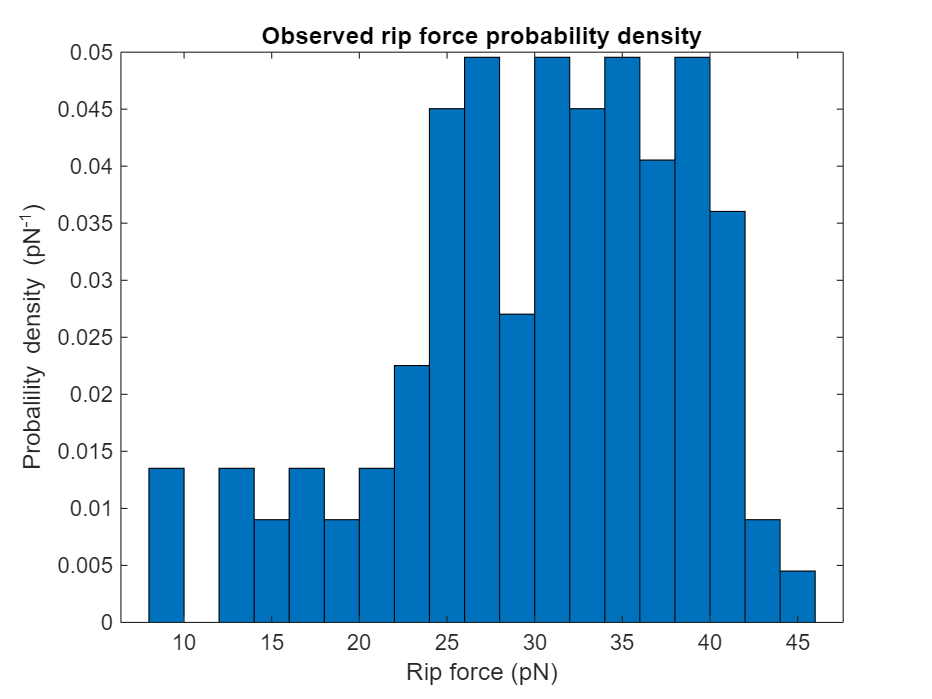

dF = 2;  % Spacing for rip force histogram and observd probalility density
[pd_obs,edges] = probdens(TRIP.Force,dF);
figure;
centres = [edges(1:end-1)+edges(2:end)]/2; % Bin centres
bar(centres,pd_obs,1);
title("Observed rip force probability density")
xlabel('Rip force (pN)')
ylabel('Probalility density (pN^-^1)')

Due to the low number of rips available we will skip the selection of rips at different temperatures. 

Now prepare the remaining inputs to fit_bell_unfold:

Tmean = mean(TRIP.Temperature);
Fdotmean = mean(TRIP.Fdot);

Initial parameter values:

dx0 = 2;log10k0 = -3; theta0 = [dx0;log10k0];

Fit Bell parameters:

[theta,theta_std] = fit_Bell_unfold(pd_obs,edges,Tmean,Fdotmean,theta0)

theta =     0.5319
   -1.9784


theta_std =     0.0468
    0.1525


The fit_Bell_unfold function calculates the model probability density for a given parameter set theta, using the function Bell_unfoldof observation_probability and seeks to minimise the sum of squared differences between the model values and the observed probabilities.  We use the same function to plot a comparison and model:

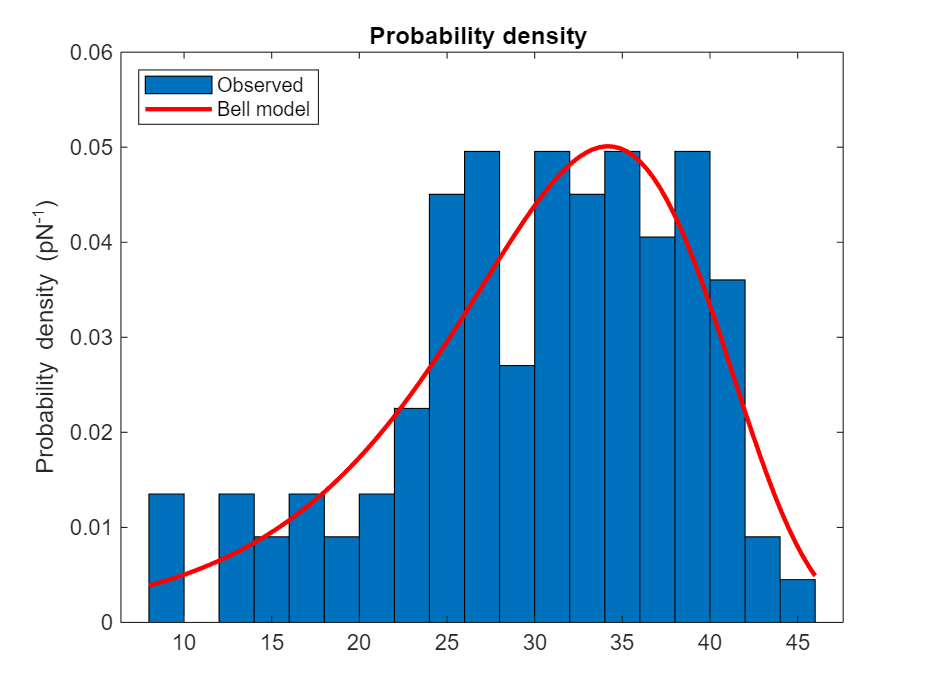

F_plot = linspace(edges(1),edges(end));  % Vector of 100 force values
pdBell = Bell_unfold_probability(theta,F_plot,Tmean,Fdotmean);
figure; bar(centres,pd_obs,1);
hold on; 
plot(F_plot,pdBell,'r','linewidth',2);
ylabel("Probability density (pN^-^1)")
title("Model and observed probability density") 
legend("Observed","Bell model","location","northwest")
title("Probability density ")

Now try the Dudko model:

DG0 = 80;
thetaD0 = [DG0;dx0;log10k0];
par.nu = 2/3;
par.model = 'DHS';
[thetaD,thetaD_std] = fit_Dudko_unfold(pd_obs,edges,Tmean,Fdotmean,thetaD0,par)

thetaD =    67.6320
    0.5951
   -2.0556


thetaD_std =   344.1709
    0.4448
    0.6011


Note that the standard deviations are much larger than for the Bell model.  For DG the standard deviation is five times larger than the best estimate value.  This indicates that the a more complex model only leads to over-parameterisation, without improving the fit.  With our data, we cannot determine more than two model parameters. 

For technical reasons, the Dudko model probability density is a function, not of thetaD directly, but of a vector I have called thetacalc which can be calculated from thetaD

DG = thetaD(1);
dx = thetaD(2);
log10k0 = thetaD(3);
thetacalc = [DG;par.nu*dx/DG;log10k0];

We use this as input to Dudko_unfold_probability:

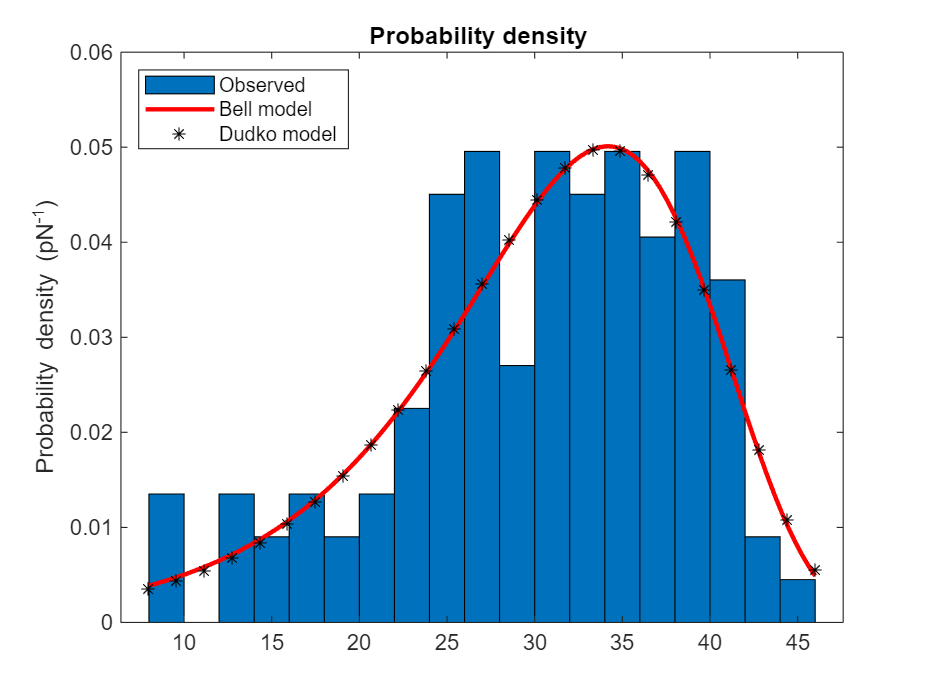

F_plotD = linspace(edges(1),edges(end),25);
pdD = Dudko_unfold_probability(thetacalc,F_plotD,Tmean,Fdotmean,par);
figure; bar(centres,pd_obs,1);
hold on; 
plot(F_plot,pdBell,'r','linewidth',2);
plot(F_plotD,pdD,'*k');
ylabel("Probability density (pN^-^1)")
title("Model and observed probability density") 
legend("Observed","Bell model","Dudko model","location","northwest")
title("Probability density ")